m1 = 0.05

m1 = 0.0500

m2 = 0.05

m2 = 0.0500

m3 = 0.05

m3 = 0.0500

m4 = 0.05

m4 = 0.0500


normal_glucose = tf([1 m3], [1 (m1+m3) (m1*m3 + m2*m4)])

normal_glucose =
 
       s + 0.05
  -------------------
  s^2 + 0.1 s + 0.005
 
Continuous-time transfer function.
Model Properties


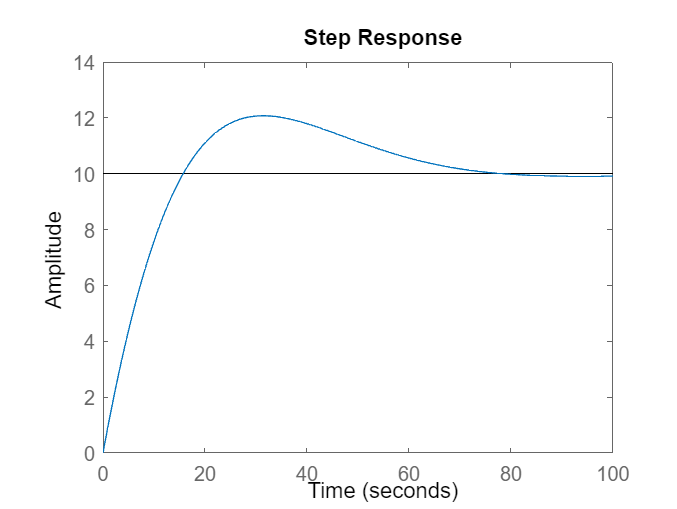

step(normal_glucose)

m1 = 0.05

m1 = 0.0500

m2 = 0.05

m2 = 0.0500

m3 = 0.05

m3 = 0.0500

m4 = 0

m4 = 0


diabetic_glucose = tf([1 m3], [1 (m1+m3) (m1*m3 + m2*m4)])

diabetic_glucose =
 
        s + 0.05
  --------------------
  s^2 + 0.1 s + 0.0025
 
Continuous-time transfer function.
Model Properties


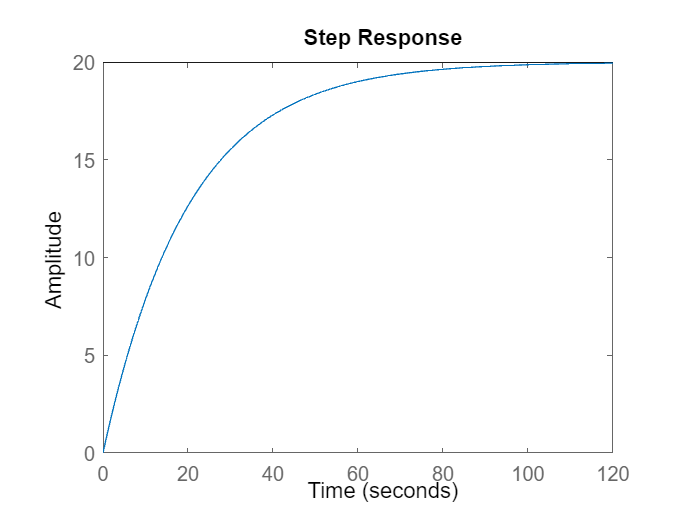

step(diabetic_glucose)

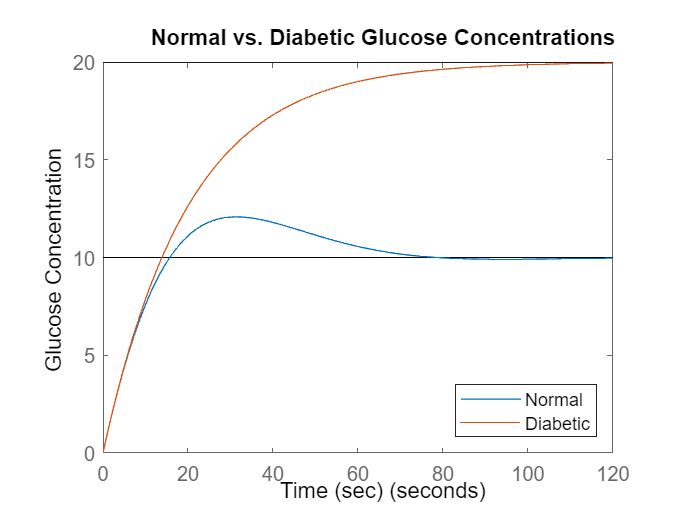

stepplot(normal_glucose, diabetic_glucose)
title("Normal vs. Diabetic Glucose Concentrations")
xlabel("Time (sec)")
ylabel("Glucose Concentration")
legend("Normal", "Diabetic", Location="southeast")